datasetPath = "C:\UAlbany\2026\Spring 2026\ECE 465 - Machine Learning\speech_commands_v0.02";

ads = audioDatastore(datasetPath,'IncludeSubfolders', true, 'FileExtensions','.wav', 'LabelSource','foldernames');

countEachLabel(ads)

ans = 35×2 table
     Label      Count
    ________    _____

    backward    1664 
    bed         2014 
    bird        2064 
    cat         2031 
    dog         2128 
    down        3917 
    eight       3787 
    five        4052 
    follow      1579 
    forward     1557 
    four        3728 
    go          3880 
    happy       2054 
    house       2113 
    learn       1575 
    left        3801 



%Split into Training and Testing data
commands = categorical(["yes","no","stop","go"]);
ads = subset(ads, ismember(ads.Labels, commands));

[adsTrain, adsTest] = splitEachLabel(ads, 0.8);

%get mel spectrograms for all training files
numTrainFiles = numel(adsTrain.Files);
XTrain = zeros(64,64,1,numTrainFiles);
YTrain = adsTrain.Labels;

for i = 1:numTrainFiles
    [audio, fs] = audioread(adsTrain.Files{i});
    
    melSpec = melSpectrogram(audio, fs);
    melSpec = log10(melSpec + 1e-6);
    
    melSpec = imresize(melSpec, [64 64]);
    
    XTrain(:,:,1,i) = melSpec;
end

%do same for test files
numTestFiles = numel(adsTest.Files);
XTest = zeros(64,64,1,numTestFiles);
YTest = adsTest.Labels;

for i = 1:numTestFiles
    [audio, fs] = audioread(adsTest.Files{i});
    
    melSpec = melSpectrogram(audio, fs);
    melSpec = log10(melSpec + 1e-6);
    
    melSpec = imresize(melSpec, [64 64]);
    
    XTest(:,:,1,i) = melSpec;
end

%
layers = [
    %tells MATLAB each input is a 64×64 grayscale image
    imageInputLayer([64 64 1])

    %applies 8 filters to detect simple patterns in the spectrogram
    convolution2dLayer(3,8,"Padding","same")

    %adds nonlinearity so the network can learn more than just simple linear patterns
    reluLayer

    %reduces the image size and keeps the strongest features
    maxPooling2dLayer(2,"Stride",2)

    %%This acts as a second layer of learning, now learning patterns
    convolution2dLayer(3,16,"Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,"Stride",2)

    %maps the extracted features to your command classes
    fullyConnectedLayer(numel(categories(YTrain)))

    %turns outputs into class probabilities
    softmaxLayer

    %computes the classification loss during training
    classificationLayer
];

%Setting Training Options
options = trainingOptions("adam","MaxEpochs", 10,"MiniBatchSize", 32,"ValidationData", {XTest, YTest},"Verbose", false, "Plots", "training-progress");

%Test accuracy
YPred = classify(net, XTest);
accuracy = mean(YPred == YTest)

%save model when first ran then just load it once it's made so it doesnt
%keep training when not necessary

if isfile("speechCommandModelv0.mat")
    load("speechCommandModelv0.mat")
else
    net = trainNetwork(XTrain,YTrain,layers,options);
    save("C:\UAlbany\2026\Spring 2026\ECE 465 - Machine Learning\speechCommandModelv0.mat","net")
end

%Now taking own voice recording and predicting
recObj = audiorecorder(16000,16,1);

disp("Start speaking")

Start speaking


recordblocking(recObj,1); % record 1 second(same length as test/training data)
disp("Recording finished")

Recording finished


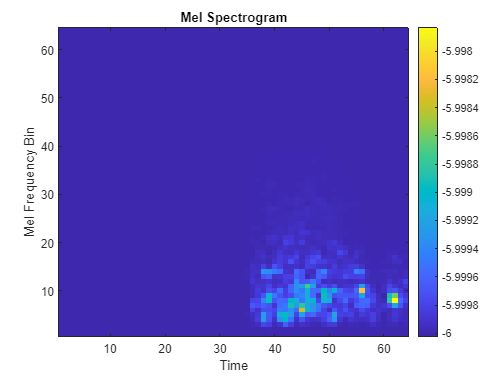


audio = getaudiodata(recObj);
fs = 16000;

melSpec = melSpectrogram(audio, fs, 'NumBands',64);
melSpec = log10(melSpec + 1e-6);
melSpec = imresize(melSpec,[64 64]);
%Make voice recording same size image for prediction model
inputImage = reshape(melSpec,[64 64 1 1]);

%show spectrogram
figure;
imagesc(inputImage);
axis xy;
xlabel("Time");
ylabel("Mel Frequency Bin");
title("Mel Spectrogram");
colorbar;


predictedWord = classify(net,inputImage)

predictedWord = categorical
     stop 



%%